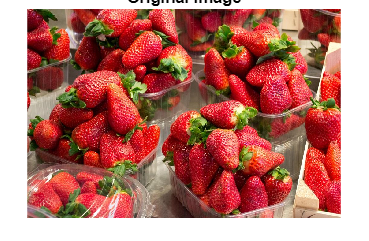

% Read the input image
inputImage = imread('strawberries.jpg'); % Replace 'your_image_path.jpg' with the actual path to your image

% Display the original image
figure;
imshow(inputImage);
title('Original Image');

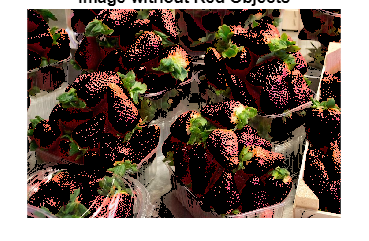


% Convert the image to the RGB color space
redChannel = inputImage(:, :, 1);
greenChannel = inputImage(:, :, 2);
blueChannel = inputImage(:, :, 3);

% Define a threshold for red color detection
redThreshold = 100; % You may need to adjust this threshold based on your specific image

% Create a binary mask for red pixels
redMask = (redChannel > redThreshold) & (greenChannel < redThreshold) & (blueChannel < redThreshold);

% Set the red pixels to black in the original image
inputImage(repmat(redMask, [1, 1, 3])) = 0;

% Display the result without red objects
figure;
imshow(inputImage);
title('Image without Red Objects');